***自定义函数***

**(1)m文件定义函数**

matlab函数基本结构:

函数调用:

遇到return语句:直接退出

函数体里面可以定义一个或者多个子函数,但是不能跨函数调用

在调用函数时,用两个永久变量nargin和nargout分别记录调用该函数时输入实参和输出实参的个数

可以单独开一个.m文件,之后在其他文件中直接调用

示例:求向量最大值与最小值

function[max,min]=max_min_values(x)
max=subfuc1(x);
min=subfuc2(x);
    function r=subfuc1(x)%子函数1
        x1=sort(x,'descend');
        r=x1(1);
    end
    function r=subfuc2(x)%子函数2
        x1=sort(x);
        r=x1(1);
    end
end
x=1:20;
[ma,mi]=max_min_values(x)

ma = 20

mi = 1

ma

ma = 20

mi

mi = 1

**(2)匿名函数**

不存在于程序文件中,数据类型是function_handle的变量相关函数

基本格式:

clear;
clc;
f=@(x,y)  x^2+y^2;
f(2,3)

ans = 13


f2=@(x,y)  x.^2+y.^2;
x=1:5;
y=0.1:0.1:0.5;
%y向量从0.1开始,每隔0.1递增直到0.5
f2(x,y)

ans =     1.0100    4.0400    9.0900   16.1600   25.2500


双重匿名函数:

f1=@(a,b)@(x)  a*x+b;
f1(2,3)

ans = 包含以下值的 function_handle :
    @(x)a*x+b


练习:

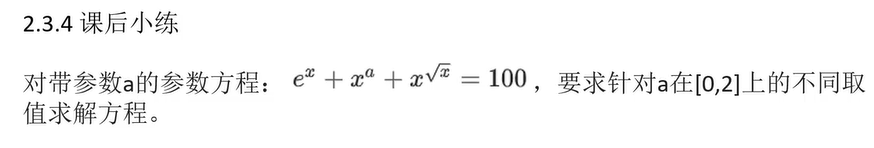

fzero函数:求解非线性函数的根

arrayfun函数:转化为对向量进行处理

f=@(a)@(x)  exp(x)+x^a+x^(sqrt(x))-100;
fzero(f(1),4)

ans = 4.3153

A=0:0.1:2;
x=@(a)fzero(f(a),4);%x(a)
X=@(A) arrayfun(@(a) x(a),A);%X(A)
Y=X(A);
C=cat(1,A,Y)

C =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000
    4.3506    4.3490    4.3470    4.3448    4.3422    4.3392    4.3357    4.3317    4.3270    4.3216    4.3153    4.3080    4.2995    4.2898    4.2784    4.2654    4.2503    4.2329    4.2128    4.1899    4.1635


**(3)特殊函数**

[**https://ww2.mathworks.cn/help/releases/R2024b/matlab/special-functions.html?searchHighlight=%E7%89%B9%E6%AE%8A%E5%87%BD%E6%95%B0&s_tid=doc_srchtitle**](https://ww2.mathworks.cn/help/releases/R2024b/matlab/special-functions.html?searchHighlight=%E7%89%B9%E6%AE%8A%E5%87%BD%E6%95%B0&s_tid=doc_srchtitle)

**(4)常用函数**

abs:绝对值(实数时取绝对值,复数时取模长)

mod:取模

sqrt:开方

exp:e的若干次方

log:取对数函数

round:四舍五入函数

clear;
clc;
x=-5;
abs(x);
x1=-3+4i;
abs(x1);
mod(11,3);
sqrt(9);
sqrt(1:9);
%format long
format short
sqrt(1:9);
sqrt(-4);
exp(1:9);
log(exp(2));
log10(34567);
round(-2.5);
round(5.4534567,3);
format long g;
round(23456.34567,3);
round(23456.34567,-3)%在小数点左侧进行四舍五入

ans =        23000


三角函数:

sin(2*pi)

ans =      -2.44929359829471e-16


**(5)其他函数:**

isempty函数:返回1代表没有,返回0代表非空

A=[1:9];
x=20;
% A==x;
find(A==x)


ans =

  空的 1×0 double 行向量



isempty(find(A==x))

ans = logical
   1


meshgrid函数:基于向量x,y中包含的坐标来返回二维网格坐标

x=0:4;
y=0:3;
[xx,yy]=meshgrid(x,y);
xx

xx =      0     1     2     3     4
     0     1     2     3     4
     0     1     2     3     4
     0     1     2     3     4


yy

yy =      0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3



z=xx.^2+yy.^2

z =      0     1     4     9    16
     1     2     5    10    17
     4     5     8    13    20
     9    10    13    18    25


rng函数:用来设置随机数种子生成可重复的随机数

seed=3;
rng(seed);
rng('shuffle')%设置不同的随机数种子
randi(10,3,3)

ans =      5     9     1
     9     7     4
     6     6     3


ismember函数:

A=[1:9];
x=5;
ismember(x,A)

ans = logical
   1
